# Model Result

## Read Data

addpath('src', 'reader', 'class')

data_file_source = "C:\Users\tedb0\Documents\debt-trap\DATA\ModelData.xlsx";

GDP_data = read_gdp_data(data_file_source);             % table with gdp related
debt_data = read_debt_data(data_file_source);           % table with debt stock 2007-2017

gdp_array = table2array(GDP_data(:, 'pc_gdp'));         % per capita real GDP
tradable_array = table2array(GDP_data(:, 'pc_trade'));  % per capita real tradable GDP


### Sri Lanka Data -- Output and Debt

% log real GDP -- Sri Lanka
sri_gdp                 = log(gdp_array(GDP_data.code == 'LKA',:));

% log tradable GDP -- Sri Lanka
sri_tradable            = log(tradable_array(GDP_data.code == 'LKA',:));

sri_debt_all            = table2array(debt_data(:, "lka_with_china"));
sri_debt_x_china        = table2array(debt_data(:, "lka_x_china"));
sri_n_gdp               = table2array(debt_data(:, "lka_gdp"));         %n = nominal
sri_n_tradable          = table2array(debt_data(:, "lka_gdp_trade"));

% debt-to-GDP   -- Sri Lanka
sri_d_t_gdp             = sri_debt_all ./ sri_n_gdp;            % debt-to-GDP-nominal
sri_d_t_tradable        = sri_debt_all ./ sri_n_tradable;       % debt-to-tradable nominal
sri_d_t_gdp_xc          = sri_debt_x_china ./ sri_n_gdp;        % debt-to-GDP, exclude China
sri_d_t_tradable_xc     = sri_debt_x_china ./ sri_n_tradable;   % debt-to-tradable, exclude China

### Pakistan Data -- Output and Debt

% per capita log real GDP -- Pakistan
pak_gdp                 = log(gdp_array(GDP_data.code == 'PAK',:));

% per capita log tradable GDP -- Pakistan
pak_tradable            = log(tradable_array(GDP_data.code == 'PAK',:));

pak_debt_all            = table2array(debt_data(:, "pak_with_china"));
pak_debt_x_china        = table2array(debt_data(:, "pak_x_china"));
pak_n_gdp               = table2array(debt_data(:, "pak_gdp"));         %n = nominal
pak_n_tradable          = table2array(debt_data(:, "pak_gdp_trade"));

% debt-to-GDP   -- Sri Lanka
pak_d_t_gdp             = pak_debt_all ./ pak_n_gdp;
pak_d_t_tradable        = pak_debt_all ./ pak_n_tradable;
pak_d_t_gdp_xc          = pak_debt_x_china ./ pak_n_gdp;
pak_d_t_tradable_xc     = pak_debt_x_china ./ pak_n_tradable;

## Calibration for the Countries

For Sri Lanka and Pakistan, several calibrations are fixed, some comes from the AR(1) estimation of output process, while $(\beta, \delta_1, \delta_2)$ are to be tuned.

- Fixed: $r^* ,\theta \;,\alpha ,\bar{h} ,a,\xi \;,\sigma$

- Tuned: $\beta \;,\delta_{1\;} ,\delta_2$

- From AR(1) process : $\rho \;,\sigma {\;}_u$

For the calibrations on the tuning parameters, three targets are required: debt-to-GDP-ratio, default frequency, and average output loss.

### Sri Lanka Calibration

sri_fixed_calibration = Calibration();
    sri_fixed_calibration.rstar   = 0.01;                            % quarterly risk-free interest rate, using US 3-month treasury bill
    sri_fixed_calibration.theta   = 0.0385;                          % probability of leaving 'bad standing' is 1-theta. When it is in bad standing, external obligations go to zero. Implies you're in bad standing for ~6.5 years, following Na et al. (2018)
    sri_fixed_calibration.alfa    = 0.65;                            % hours elasticity of nontraded output (rough estimate based on exports as % of GDP)
    sri_fixed_calibration.hbar    = 1;                               % full-employment hours (normalised to unity)
    sri_fixed_calibration.a       = 0.4;                             % share of tradables (as a % of total consumption) (based on actual GDP data, tradable/GDP)
    sri_fixed_calibration.xi      = 0.5;                             % elasticity of substitution between traded and nontraded goods (estimates vary considerably; 1/sigg (where sigg=2) is Na et al;
    sri_fixed_calibration.sigg    = 1/sri_fixed_calibration.xi;          % elasticity of substitution: inverse intertemporal (Na et al. 2018)
    sri_fixed_calibration.gamma   = 1.109;  

% target when output is proxied by real GDP
sri_target_when_gdp = struct();
    sri_target_when_gdp.debt_ratio      = 0.75;                      % 75% per quarter
    sri_target_when_gdp.default_freq    = 2.6;                       % 2.6 times per centurty
    sri_target_when_gdp.output_loss     = 0.07;                      % 7% output loss per year

% target when output is proxied by real tradable GDP
sri_target_when_tradable = struct();
    sri_target_when_tradable.debt_ratio     = 1.75;                  % The denominator is now tradable GDP
    sri_target_when_tradable.default_freq   = 2.6;
    sri_target_when_tradable.output_loss    = 0.07;

### Pakistan Calibration

pak_fixed_calibration = Calibration();
    pak_fixed_calibration.rstar   = 0.01;                            % quarterly risk-free interest rate, using US 3-month treasury bill
    pak_fixed_calibration.theta   = 0.0417;                          % probability of leaving 'bad standing' is 1-theta. When it is in bad standing, external obligations go to zero. Implies you're in bad standing for ~6.5 years, following Na et al. (2018)
    pak_fixed_calibration.alfa    = 0.4;                            % hours elasticity of nontraded output (rough estimate based on exports as % of GDP)
    pak_fixed_calibration.hbar    = 1;                               % full-employment hours (normalised to unity)
    pak_fixed_calibration.a       = 0.45;                             % share of tradables (as a % of total consumption) (based on actual GDP data, tradable/GDP)
    pak_fixed_calibration.xi      = 0.5;                             % elasticity of substitution between traded and nontraded goods (estimates vary considerably; 1/sigg (where sigg=2) is Na et al;
    pak_fixed_calibration.sigg    = 1/pak_fixed_calibration.xi;          % elasticity of substitution: inverse intertemporal (Na et al. 2018)
    pak_fixed_calibration.gamma   = 1.048; 


% target when output is proxied by real GDP
pak_target_when_gdp = struct();
    pak_target_when_gdp.debt_ratio      = 0.44;                      % 75% per quarter
    pak_target_when_gdp.default_freq    = 2.6;                       % 2.6 times per centurty
    pak_target_when_gdp.output_loss     = 0.07;                      % 7% output loss per year

% target when output is proxied by real tradable GDP
pak_target_when_tradable = struct();
    pak_target_when_tradable.debt_ratio     = 1.02;                  % The denominator is now tradable GDP
    pak_target_when_tradable.default_freq   = 2.6;
    pak_target_when_tradable.output_loss    = 0.07;

Note that the targeting debt-to-tradable-GDP ratio for Sri Lanka exceeds the limit set by Na et al. (2018), hence an adjustment on the upper bound is needed.

## Output Process

This section processes the output process for Sri Lanka and Pakistan, on real GDP and real tradable GDP, respectively.

The `OutputProcess` class runs the filter, estimates the AR(1), and generates the trasition probability matrix sequentially.

year_range = 1960:2021;
if isfile("output_processes.mat")
    load output_processes.mat
else
% Sri Lanka
output_proxy_sri_gdp_hp      = OutputProcess(sri_gdp,year_range, "HP");
output_proxy_sri_gdp_logq    = OutputProcess(sri_gdp,year_range, "log-q");
output_proxy_sri_trad_hp     = OutputProcess(sri_tradable,year_range, "HP");
output_proxy_sri_trad_logq   = OutputProcess(sri_tradable,year_range, "log-q");

% Pakistan

output_proxy_pak_gdp_hp      = OutputProcess(pak_gdp,year_range, "HP");
output_proxy_pak_gdp_logq    = OutputProcess(pak_gdp,year_range, "log-q");

output_proxy_pak_trad_hp     = OutputProcess(pak_tradable,year_range, "HP");
output_proxy_pak_trad_logq   = OutputProcess(pak_tradable,year_range, "log-q");

% save all in advance
save output_processes.mat output_proxy_sri_gdp_hp output_proxy_sri_gdp_logq ...
    output_proxy_sri_trad_hp output_proxy_sri_trad_logq ...
    output_proxy_pak_gdp_hp output_proxy_pak_gdp_logq ...
    output_proxy_pak_trad_hp  output_proxy_pak_trad_logq
end

Note that GDP data is less volatile than tradable

output_proxy_sri_gdp_hp.unconditional_std*100

ans = 2.9826

output_proxy_sri_trad_hp.unconditional_std*100

ans = 4.3675

and HP filter is less volatile than log-quadratic detrend

output_proxy_sri_trad_hp.unconditional_std*100

ans = 4.3675

output_proxy_sri_trad_logq.unconditional_std*100

ans = 7.3759

and in general, Pakistan is less volatile than Sri Lanka

output_proxy_pak_trad_logq.unconditional_std*100

ans = 4.5519

output_proxy_sri_trad_logq.unconditional_std*100

ans = 7.3759

# Running Model - HP Filter

I wrote a `Model` class in Matlab that handles and encapsulates the following.

Encapsulate:

- Output Process

- Calibration

- Value Function

Executes:

- Search for best tuning parameters

- VFI

- Simulation

Note that plots for default set is decoupled into a separate class `DefaultSetPlotter`

## `GDP + HP`

% try load file first

if isfile("result\model_sri_gdp_hp.mat")   
    load("result\model_sri_gdp_hp.mat")
else
    
    model_sri_gdp_hp = Model(sri_fixed_calibration, output_proxy_sri_gdp_hp);
    model_sri_gdp_hp.set_targets(sri_target_when_gdp);
 
    
    model_sri_gdp_hp.run();

    save("result/model_sri_gdp_hp.mat", "model_sri_gdp_hp")

end
if  isfile("result\model_pak_gdp_hp.mat")
    load("result\model_pak_gdp_hp.mat")
else
  
    model_pak_gdp_hp = Model(pak_fixed_calibration, output_proxy_pak_gdp_hp);
    model_pak_gdp_hp.set_targets(pak_target_when_gdp);
    
    model_pak_gdp_hp.run();

    save("result/model_pak_gdp_hp.mat", "model_pak_gdp_hp")
end

## Tradable + HP

% try load file first

if isfile("result\model_sri_tradable_hp.mat")
   
    load("result\model_sri_tradable_hp.mat")

else
    % debt needs to be wider for proxy using tradable output
    wider_debt = sri_fixed_calibration; wider_debt.d_range = [0 2.5];
    model_sri_tradable_hp = Model(wider_debt, output_proxy_sri_trad_hp);
    model_sri_tradable_hp.set_targets(sri_target_when_tradable);
    
    model_sri_tradable_hp.run();

    save("result/model_sri_tradable_hp.mat", "model_sri_tradable_hp")

end
if isfile("result\model_pak_tradable_hp.mat")
   
    load("result\model_pak_tradable_hp.mat")
else
    
    model_pak_tradable_hp = Model(pak_fixed_calibration, output_proxy_pak_trad_hp);
    model_pak_tradable_hp.set_targets(pak_target_when_tradable);
    
    model_pak_tradable_hp.run();

    save("result/model_pak_tradable_hp.mat", "model_pak_tradable_hp")

end

Note that cyclical components obtained via HP-filter yields a too small output volitility

model_sri_gdp_hp.optimal_calibration_grid

ans =     0.6902   -0.4826    0.5489


model_sri_tradable_hp.optimal_calibration_grid

ans =     0.6919   -0.4391    0.5530


model_pak_gdp_hp.optimal_calibration_grid

ans =     0.6598   -0.5108    0.5667


model_pak_tradable_hp.optimal_calibration_grid

ans =     0.6252   -0.5148    0.5789


This yields a low beta value of 0.74 for Sri Lanka, and 0.69 for Pakistan, if targeting GDP

# `Default Plot -- HP`

## `Sri Lanka`

%ds_sri_gdp_hp = DefaultSetPlotter(model_sri_gdp_hp, sri_d_t_gdp, 2007:2017)
%ds_sri_gdp_hp.plot()

ds_sri_tradable_hp = DefaultSetPlotter(model_sri_tradable_hp, sri_d_t_tradable , 2007:2017);
ds_sri_tradable_hp.add_range([0.9 1.15], [100 250]);
ds_sri_tradable_hp.plot()

ans =   Figure (55) with properties:

      Number: 55
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


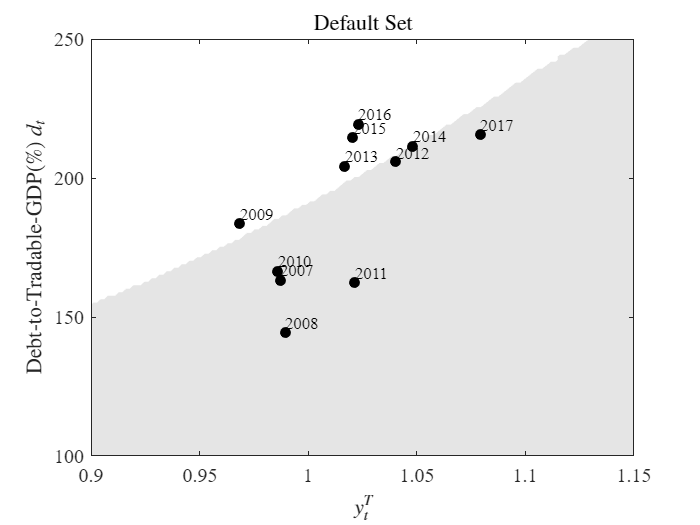

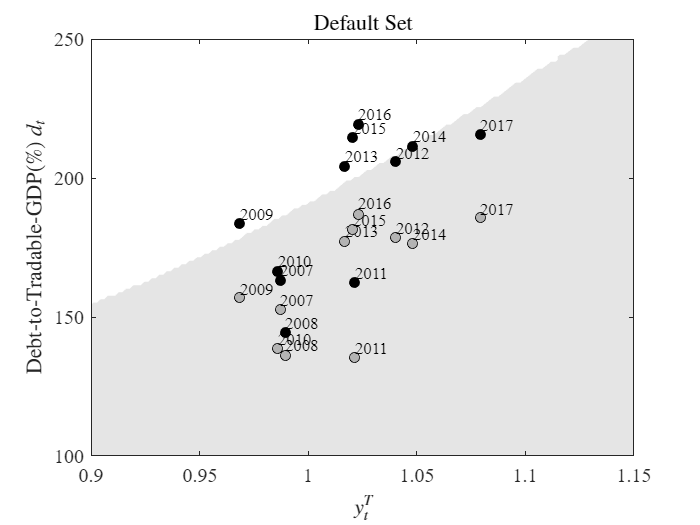

ans =   Figure (56) with properties:

      Number: 56
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_sri_tradable_hp.add_comparison(sri_d_t_tradable_xc)

fig_sri_prob = ds_sri_tradable_hp.plot_prob()

fig_sri_prob =   Figure (57) with properties:

      Number: 57
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


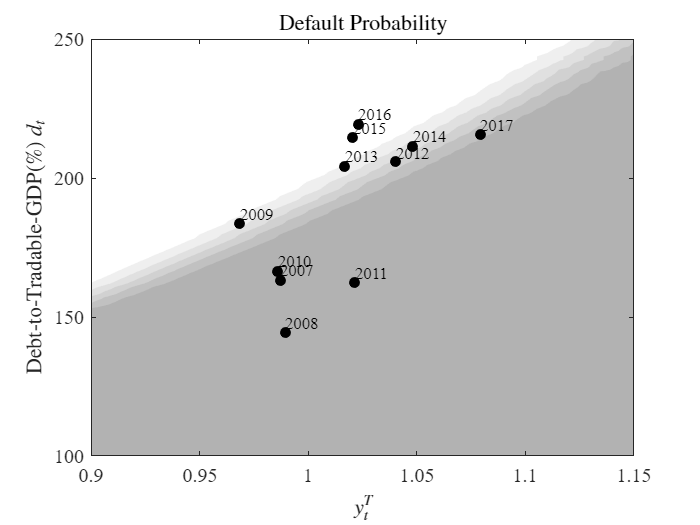

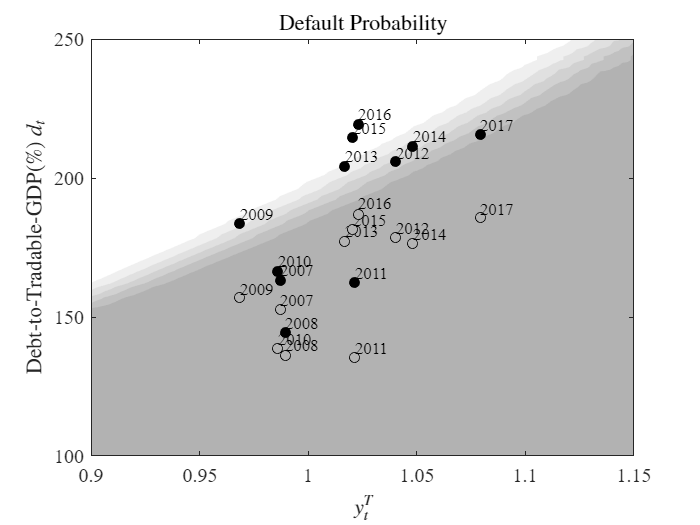

ans =   Figure (58) with properties:

      Number: 58
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_sri_tradable_hp.add_comparison(sri_d_t_tradable_xc, fig_sri_prob)

## `Pakistan`

plot_range = [2010 2013:2017];
pak_d_t_gdp_plot = pak_d_t_gdp(plot_range - 2006);
pak_d_t_tradable_plot = pak_d_t_tradable(plot_range - 2006);
pak_d_t_gdp_xc_plot = pak_d_t_gdp_xc(plot_range - 2006);
pak_d_t_tradable_xc_plot = pak_d_t_tradable_xc(plot_range - 2006);


%ds_pak_gdp_hp = DefaultSetPlotter(model_pak_gdp_hp, pak_d_t_gdp_plot, plot_range)
%ds_pak_gdp_hp.plot()

ds_pak_tradable_hp = DefaultSetPlotter(model_pak_tradable_hp, pak_d_t_tradable_plot, plot_range)

ds_pak_tradable_hp =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [6×1 double]
    plot_year_range: [2010 2013 2014 2015 2016 2017]
                fig: []
             xrange: [-1 -1]
             yrange: [-1 -1]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


ds_pak_tradable_hp.add_range([0.92 1.08], [50 150])

ans =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [6×1 double]
    plot_year_range: [2010 2013 2014 2015 2016 2017]
                fig: []
             xrange: [0.9200 1.0800]
             yrange: [50 150]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


ds_pak_tradable_hp.plot()

ans =   Figure (59) with properties:

      Number: 59
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


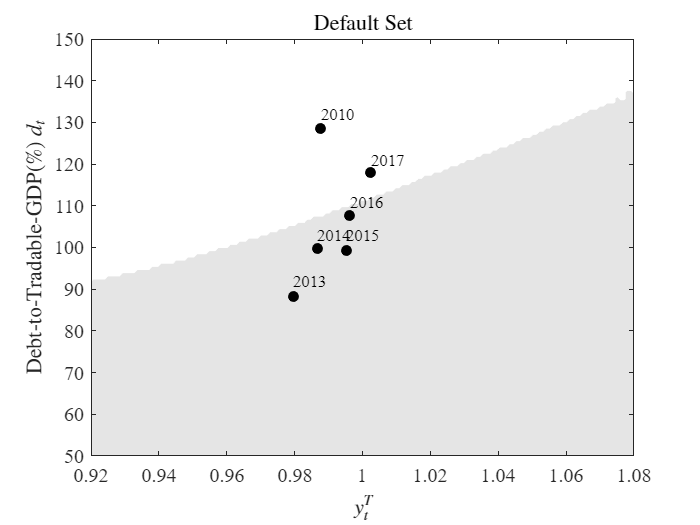

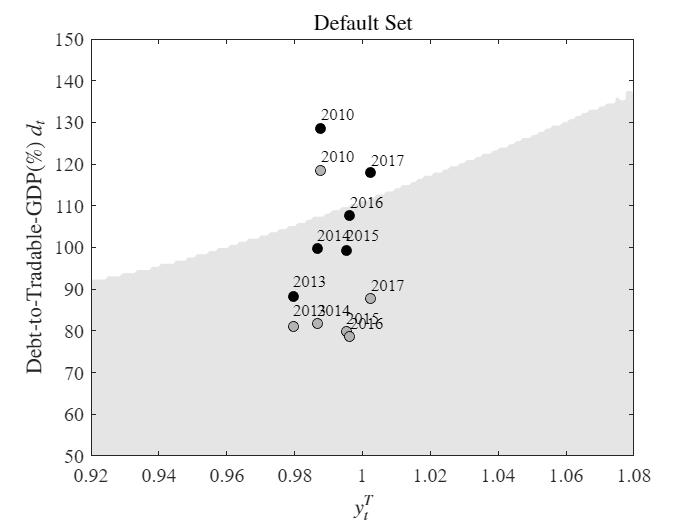

ans =   Figure (60) with properties:

      Number: 60
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_pak_tradable_hp.add_comparison(pak_d_t_tradable_xc_plot)

fig_pak_prob = ds_pak_tradable_hp.plot_prob()

fig_pak_prob =   Figure (61) with properties:

      Number: 61
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


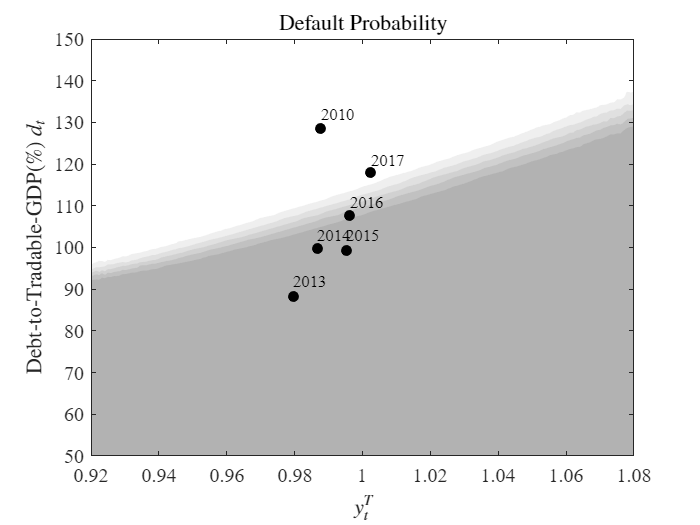

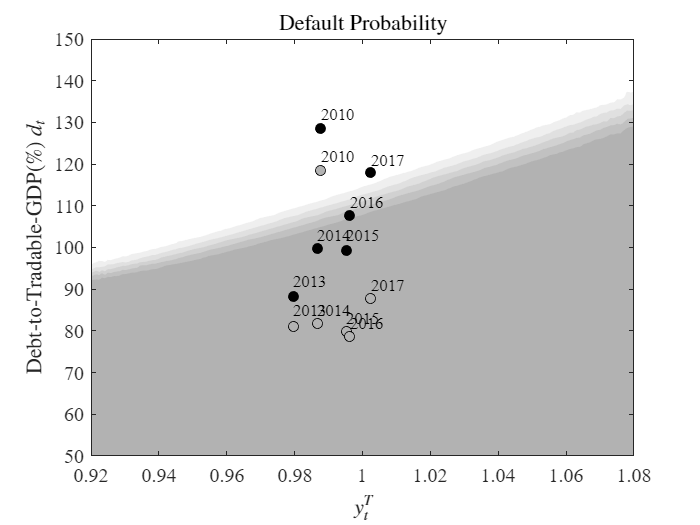

ans =   Figure (62) with properties:

      Number: 62
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_pak_tradable_hp.add_comparison(pak_d_t_tradable_xc_plot, fig_pak_prob)

# Running Model - Log-quadratic Filter

Na et al. (2018)  uses an log-quadratic filter instead

## `GDP + Log-Q`

% try load file first

if isfile("result\model_sri_gdp_logq.mat")

    load("result\model_sri_gdp_logq.mat")

else
    
    model_sri_gdp_logq = Model(sri_fixed_calibration, output_proxy_sri_gdp_logq);
    model_sri_gdp_logq.set_targets(sri_target_when_gdp);
    
    
    model_sri_gdp_logq.run();

    save("result/model_sri_gdp_logq.mat", "model_sri_gdp_logq")

end
if isfile("result\model_pak_gdp_logq.mat")
   
    load("result\model_pak_gdp_logq.mat")
else
    
    model_pak_gdp_logq = Model(pak_fixed_calibration, output_proxy_pak_gdp_logq);
    model_pak_gdp_logq.set_targets(pak_target_when_gdp);
    
    model_pak_gdp_logq.run();

    save("result/model_pak_gdp_logq.mat", "model_pak_gdp_logq")

end

## Tradable + Log-Q

% try load file first

if isfile("result\model_sri_tradable_logq.mat")
   
    load("result\model_sri_tradable_logq.mat")
else
    % debt needs to be wider for proxy using tradable output
    wider_debt = sri_fixed_calibration; wider_debt.d_range = [0 2.5];
    model_sri_tradable_logq = Model(wider_debt, output_proxy_sri_trad_logq);
    model_sri_tradable_logq.set_targets(sri_target_when_tradable);
    
    model_sri_tradable_logq.run();

    save("result/model_sri_tradable_logq.mat", "model_sri_tradable_logq")

end
if isfile("result\model_pak_tradable_logq.mat")
   
   load("result\model_pak_tradable_logq.mat")
else
    
    model_pak_tradable_logq = Model(pak_fixed_calibration, output_proxy_pak_trad_logq);
    model_pak_tradable_logq.set_targets(pak_target_when_tradable);
    
    model_pak_tradable_logq.run();

    save("result/model_pak_tradable_logq.mat", "model_pak_tradable_logq")

end

Now that log-quadratic detrending creates a higher volatility for each output processes, the discount factor $\beta$s yield higher value relative to the previous results.

model_sri_gdp_logq.optimal_calibration_grid

ans =     0.7012   -0.3281    0.4156


model_sri_tradable_logq.optimal_calibration_grid

ans =     0.6320   -0.2878    0.4248


model_pak_gdp_logq.optimal_calibration_grid

ans =     0.8959   -0.4211    0.4799


model_pak_tradable_logq.optimal_calibration_grid

ans =     0.8627   -0.4167    0.4973


# `Default Plot -- LogQ`

## `Sri Lanka`

plot_range = 2007:2017;
sri_d_t_gdp_plot = sri_d_t_gdp(plot_range - 2006);
sri_d_t_tradable_plot = sri_d_t_tradable(plot_range - 2006);

ds_sri_gdp_logq = DefaultSetPlotter(model_sri_gdp_logq, sri_d_t_gdp_plot, plot_range)

ds_sri_gdp_logq =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [11×1 double]
    plot_year_range: [2007 2008 2009 2010 2011 2012 2013 2014 2015 2016 2017]
                fig: []
             xrange: [-1 -1]
             yrange: [-1 -1]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


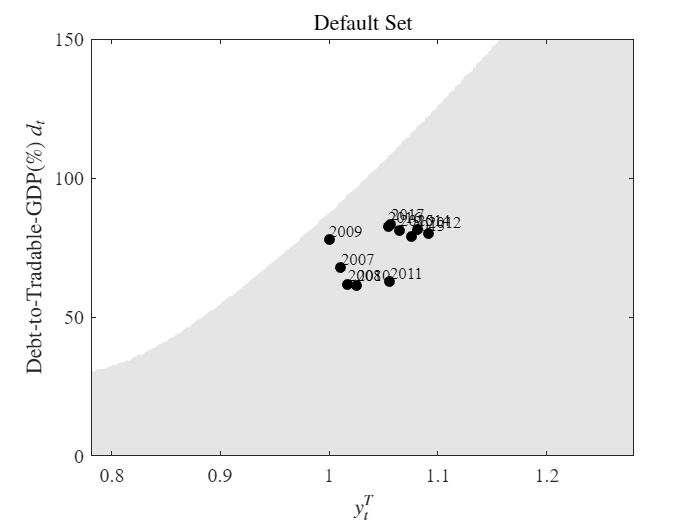

ans =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_sri_gdp_logq.plot()

ds_sri_tradable_logq = DefaultSetPlotter(model_sri_tradable_logq, sri_d_t_tradable_plot, plot_range)

ds_sri_tradable_logq =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [11×1 double]
    plot_year_range: [2007 2008 2009 2010 2011 2012 2013 2014 2015 2016 2017]
                fig: []
             xrange: [-1 -1]
             yrange: [-1 -1]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


ds_sri_tradable_logq.add_range([0.9 1.15], [100 250])

ans =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [11×1 double]
    plot_year_range: [2007 2008 2009 2010 2011 2012 2013 2014 2015 2016 2017]
                fig: []
             xrange: [0.9000 1.1500]
             yrange: [100 250]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


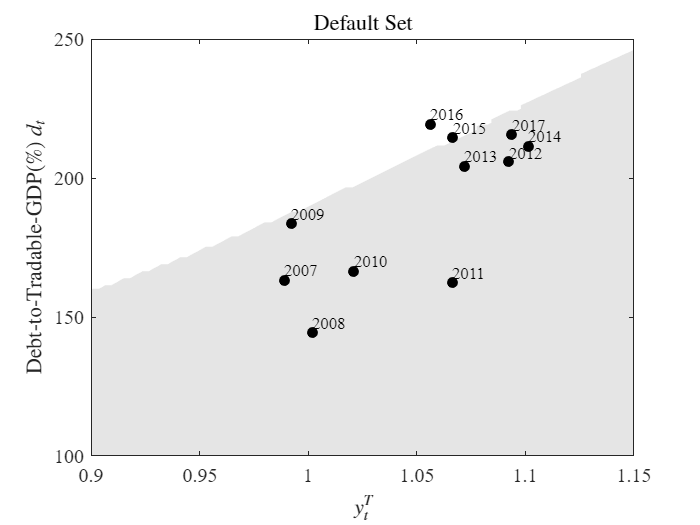

ans =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_sri_tradable_logq.plot()

## `Pakistan`

plot_range = [2010 2013:2017];
pak_d_t_gdp_plot = pak_d_t_gdp(plot_range - 2006)

pak_d_t_gdp_plot =     0.3734
    0.2623
    0.2947
    0.2880
    0.2943
    0.3193


pak_d_t_tradable_plot = pak_d_t_tradable(plot_range - 2006)

pak_d_t_tradable_plot =     0.8683
    0.5955
    0.6733
    0.6712
    0.7271
    0.7969



ds_pak_gdp_logq = DefaultSetPlotter(model_pak_gdp_logq, pak_d_t_gdp_plot, plot_range)

ds_pak_gdp_logq =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [6×1 double]
    plot_year_range: [2010 2013 2014 2015 2016 2017]
                fig: []
             xrange: [-1 -1]
             yrange: [-1 -1]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


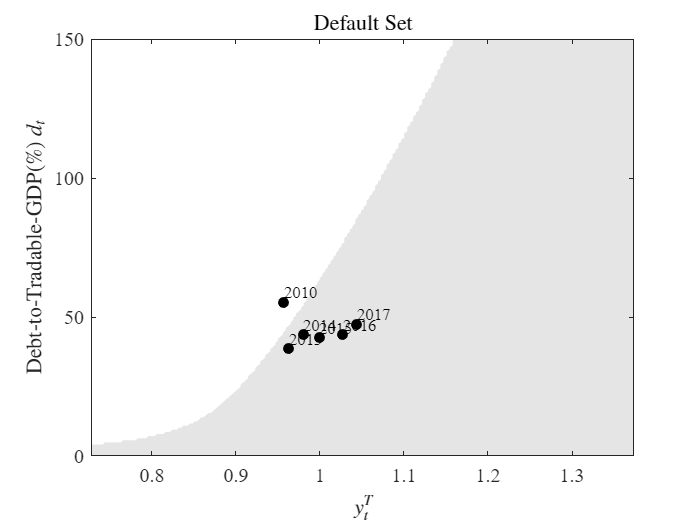

ans =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


ds_pak_gdp_logq.plot()


ds_pak_tradable_logq = DefaultSetPlotter(model_pak_tradable_logq, pak_d_t_tradable_plot, plot_range)

ds_pak_tradable_logq =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [6×1 double]
    plot_year_range: [2010 2013 2014 2015 2016 2017]
                fig: []
             xrange: [-1 -1]
             yrange: [-1 -1]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


ds_pak_tradable_logq.add_range([0.92 1.08], [50 150])

ans =   DefaultSetPlotter with properties:

              model: [1×1 Model]
        debt_series: [6×1 double]
    plot_year_range: [2010 2013 2014 2015 2016 2017]
                fig: []
             xrange: [0.9200 1.0800]
             yrange: [50 150]
     output_process: [1×1 OutputProcess]
         year_range: [62×1 int16]


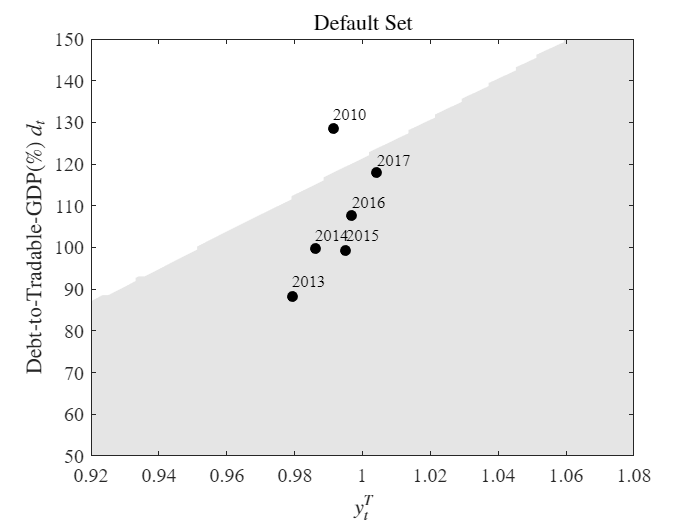

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties



ds_pak_tradable_logq.plot()